**Data import, H = 80mm**

clear;
filename = 'Piezo stack impulse test';
sheetname1 = 'Voltage across R without C H80';
data = readmatrix(filename,'Sheet',sheetname1);
data = data(2:end,:);

**Voltage and Energy output of each Resistance**

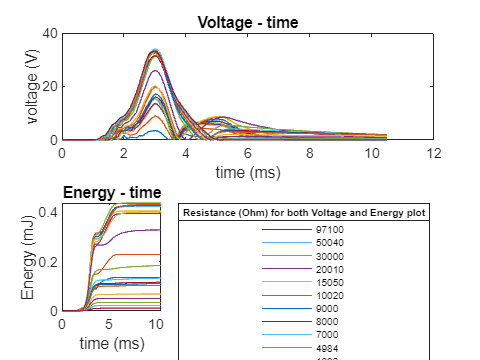

clf
Power_all = zeros(1,ceil(size(data,2)/10));
Resistor = zeros(1,ceil(size(data,2)/10));
for i = 1:ceil(size(data,2)/10)
    [volt,time] = firstImpulse(data(:,10*i-9:10*i)); %at each R
    subplot(2,1,1);
    plot(time.*1e3,volt) %plot in ms
    hold on
    [Energy,sum_Energy,Power] = volt2energy(volt,time,data(1,10*i-9));
    Power_all(i) = Power;
    Resistor(i) = data(1,10*i-9); %Resistor's value of each loop
    subplot(2,1,2);
    plot(time.*1e3,Energy.*1e3) %plot in ms and mJ
    hold on
end
hold off

legend_label = cellfun(@num2str, num2cell(Resistor), 'UniformOutput', false);
subplot(2,1,1);
title('Voltage - time')
xlabel('time (ms)')
ylabel('voltage (V)')

subplot(2,1,2);
title('Energy - time')
xlabel('time (ms)')
ylabel('Energy (mJ)')
lgd = legend(legend_label,'NumColumns',1,'Location','eastoutside','FontSize',6,'Direction','reverse');
title(lgd,'Resistance (Ohm) for both Voltage and Energy plot')

**Power and Voltage output vs. Resistance**

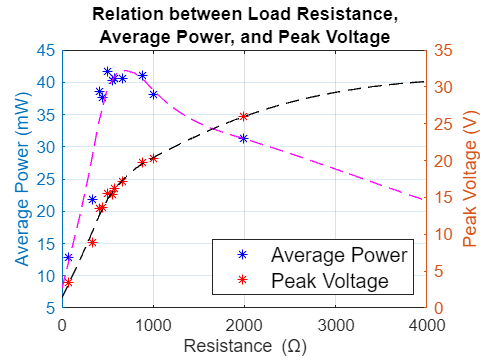

figure;
[Resistor_sorted, idx] = sort(Resistor);
Power_all_sorted = Power_all(idx) .* 1e3; %Power output in [mW] unit

%fit curve
yyaxis left;
load enso
Power_R = fit(transpose(Resistor_sorted),transpose(Power_all_sorted),'smoothingspline','SmoothingParam',1e-6);
plot(transpose(Resistor_sorted),transpose(Power_all_sorted),'*b')
hold on
plot(Power_R,'m')
hold off
ylabel('Average Power (mW)')

volt_max = transpose(data(3,1:10:end-9));
yyaxis right;
volt_R = fit(transpose(Resistor_sorted),volt_max,'smoothingspline','SmoothingParam',1e-6);
plot(transpose(Resistor_sorted),volt_max,'*r')
hold on
plot(volt_R,'k')
hold off
ylabel('Peak Voltage (V)')

xlim([0,4000])
legend('Average Power','','Peak Voltage','','Location','southeast','FontSize',12)

xlabel('Resistance (\Omega)')
grid on
title({'Relation between Load Resistance,';'Average Power, and Peak Voltage'})

## **This part is for presentation slide**

**Volt-Time plot at R = 885 Ohm**

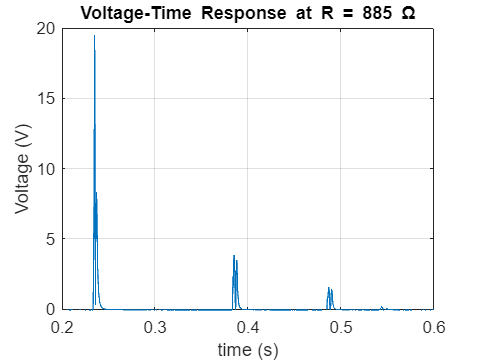

clf

% Voltage-time response of R=885 Ohm and H = 80 mm over the entire time period
volt_R885 = data(:,83);
time_R885 = data(:,82);
createGraphWithProperties(time_R885,volt_R885, ...
    'title','Voltage-Time Response at R = 885 \Omega', ...
    'xlabel','time (s)','ylabel','Voltage (V)','xlim',[0.2,0.6])

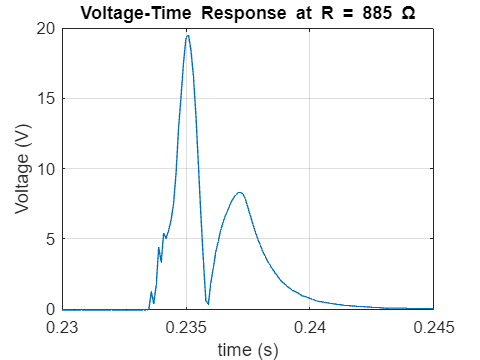


% Zoom in the first peak
createGraphWithProperties(time_R885,volt_R885, ...
    'title','Voltage-Time Response at R = 885 \Omega', ...
    'xlabel','time (s)','ylabel','Voltage (V)','xlim',[0.23,0.245])

**Energy-Time plot at R = 885 Ohm**

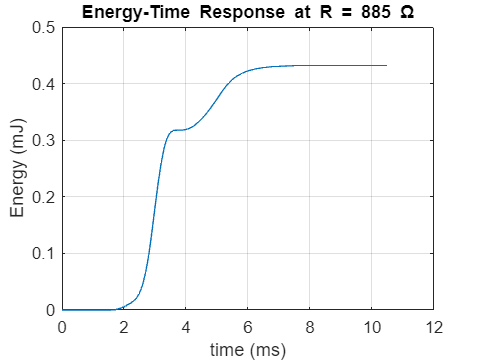

[energy_R885, sum_energy_R885, power_R885] = data2energyStack(data(:,81:90),885);

% Energy-Time response of R=885 Ohm and H = 80 mm over the time period
createGraphWithProperties(time*1e3,energy_R885 *1e3, ...
    'title','Energy-Time Response at R = 885 \Omega', ...
    'xlabel','time (ms)','ylabel','Energy (mJ)')